## Q3. Microscoping Modelling

#### a. Analytical expression of maximum flow


$$v\left(\rho \right)=v_0 {\left(1-\frac{\rho }{\rho_{\max } }\right)}^2$$
 

The flow for any velocity is given as 


$$f=v\rho$$



$$f=v_0 \rho -\frac{2v_0 \rho^2 }{\rho_{\max } }+\frac{v_0 \rho^3 }{{\rho^2 }_{\max } }$$



$$\frac{\mathrm{d}}{\mathrm{d}\rho }f=v_0 -\frac{4v_0 \rho }{\rho_{\max } }+\frac{3v_0 \rho^2 }{{\rho^2 }_{\max } }$$


The maximum will occur when


$$\frac{d}{\mathrm{d}\rho }f=0$$


This occurs when (solving for density)

$\rho =\frac{\rho_{\max } }{3}$ or when its equal to maximum density, but this means the flow has stopped.

and so the maximum flow is 


$$f_{\max } =\frac{v\rho_{\max } }{3}$$
 

#### b. Theoretical lower bound of exits N

Theoretical maximum velocity:


$$v\left(\rho =\frac{\rho_{\max } }{3}\right)=\frac{4}{9}v_0$$


So the maximum flow rate of people:


$$f_{\max } =\frac{4v_0 \rho_{\max } }{27}\;\left\lbrack {\textrm{people}\;m}^{-1} s^{-1} \right\rbrack$$


Evacuation area:


$$\textrm{area}=10N\;\left\lbrack m\right\rbrack$$


Evacuation time:

time = 300s

Lower bound of N:


$$\frac{60000}{f_{\max } }=300\times 10\;N\;$$



$$N_{\textrm{LB}} =\frac{135}{v_0 \rho_{\max } }$$


#### c. Numerical value

N = round(135 / (1.3*8))

N = 13

#### d. Detailed microscopic model

Social force model definition:


$$\frac{\mathrm{d}}{\mathrm{d}t}v_{\alpha } \left(t\right)=f_{\alpha } \left(t\right)+\textrm{noise}$$



$$f_{\alpha } \left(t\right)=\frac{1}{\tau_{\alpha } }\left(v_{0_{\alpha } } -v_{\alpha } \right)+\sum_{\beta \left(\not= \alpha \right)} f_{\alpha \beta } \left(t\right)+\sum_i f_{\alpha i} \left(t\right)$$


The equation above shows that the force on a pedestrian is equal to the sum of the acceleration to desired velocity, the sum of forces from other pedestrians, and the sum of forces from boundaries.

- **Each pedestrian is a fan of one of the two teams currently playing. Assume a random allocation of team affinity at the start of the simulation. **

At the start of the simulation, each pedestrian is randomly assigned to one of the two teams (Team A or Team B). Let $T_{\alpha }$ denote the assignment of pedestrian $\alpha$.	


$$\begin{array}{l}
T_{\alpha } =1\;\textrm{or}\;0\\
\textrm{with}:\\
P\left(X=X\right)=\;\;0\ldotp 5\;
\end{array}$$


- **A pedestrian’s desired walking speed will be 50% higher than normal if he/she is currently in a location where there is a majority of fans supporting the other team (within a 10 m radius around the person). 	**	

So at each timestep, the following is calculated:


$$v_{0_{\alpha } } =v_{0_{\alpha } } \times \left(1+0\ldotp 5\times M\right)$$
 

Where M is calculated as followe:

$M\left(\alpha \right)=\frac{\sum_{\beta \;\left(\not= \alpha \right)} 1\;|\;\left(d_{\alpha \beta } <10\;\&\;T_{\beta \;} \not= T_{\alpha } \right)}{\sum_{\beta \;\left(\not= \alpha \right)} 1\;|\;\left(d_{\alpha \beta } <10\;\;\&\;T_{\beta } =T_{\alpha } \right)}$ , $d_{\alpha \beta \;} =\textrm{distance}\;\textrm{between}\;\textrm{supporters}$

the piecewise function:


$$\begin{array}{l}
M=1\;\left\lbrace M\left(\alpha \right)>1\right\rbrace \\
M=0\;\left\lbrace M\left(\alpha \right)\le 1\right\rbrace 
\end{array}$$


(Giving the ratio of supporters of the other team vs supporters of own team and using that as the 1 or 0 piecewise function.)

- **A pedestrian α will be subject to a strong repulsive social force from other pedestrians (β ̸= α) that are (i) within a 5 m radius around the person; and (ii) supporting the other team; and (iii) are located within the 180◦ semi-circle in front of α (i.e., in the direction of motion of α). **


$$f_{\alpha \beta } =w\left(\theta_{\alpha \beta } \right)g\left(d_{\alpha \beta } \right)$$
		

The repulsive force is composed of an angular and distance component. The distance component is modelled as follows:			


$${g\left(d_{\alpha \beta } \right)} =A\times \exp \left(\frac{R-d_{\alpha \beta } }{B}\right)\hat{d_{\alpha \beta } }$$


$F_{\alpha \beta }$ is the force of repulsion from pedestrian $\alpha \;\textrm{to}\;\beta$, acting along the direction of the normalised vector between pedestrians $\hat{d}$.

A is parameter constant that will determine the strength of the repulsive force

B is a parameter constant determining how the repulsive force decays with distance between pedestrians. With a small value of B, e.g. 0.1, the force will be very high within 5m and decay very quickly as the distance increases further.

The force is only applied if the distance $d_{\alpha \beta \;} <R$ is less than the radius (5m)

The angular component can be modelled as follows:


$$w\left(\theta_{\alpha \beta } \right)=\lambda +\left(1-\lambda \right)\frac{1-\cos \left(\theta_{\alpha \beta } \right)}{2}$$
 

If $\lambda =1,\textrm{the}\;\textrm{force}\;\textrm{is}\;\textrm{equal}\;\textrm{for}\;\textrm{all}\;\textrm{values}\;\textrm{of}\;\theta ,\textrm{if}\;\lambda =0,\textrm{the}\;\textrm{force}\;\textrm{is}\;\textrm{only}\;\textrm{active}\;\textrm{for}\;\frac{\pi }{2}\le \theta \le 3\frac{\pi }{2}$

For the purpose of the model, it can be either modelled by using a value of $\lambda =0$, and this will give a cardiod-like shape in the forward direction.

or a piecewise function defined as:


$$w\left(\theta_{\alpha \beta } \right)\;=1,\;\;\;\;\frac{\pi }{2}\le \theta \le 3\frac{\pi }{2}$$



$$w\left(\theta_{\alpha \beta } \right)\;=0,\;\;\;\mathrm{else}$$


Calculating the angle, where v is the velocity vector of the pedestrians. A head-on course results in an angle of pi - the point where a repulsive force is required.


$$\cos \left(\theta_{\alpha \;\beta } \right)=\frac{v_{\alpha } \cdot v_{\beta } }{|v_{\alpha } |\;|v_{\beta } |}$$


#### Example code

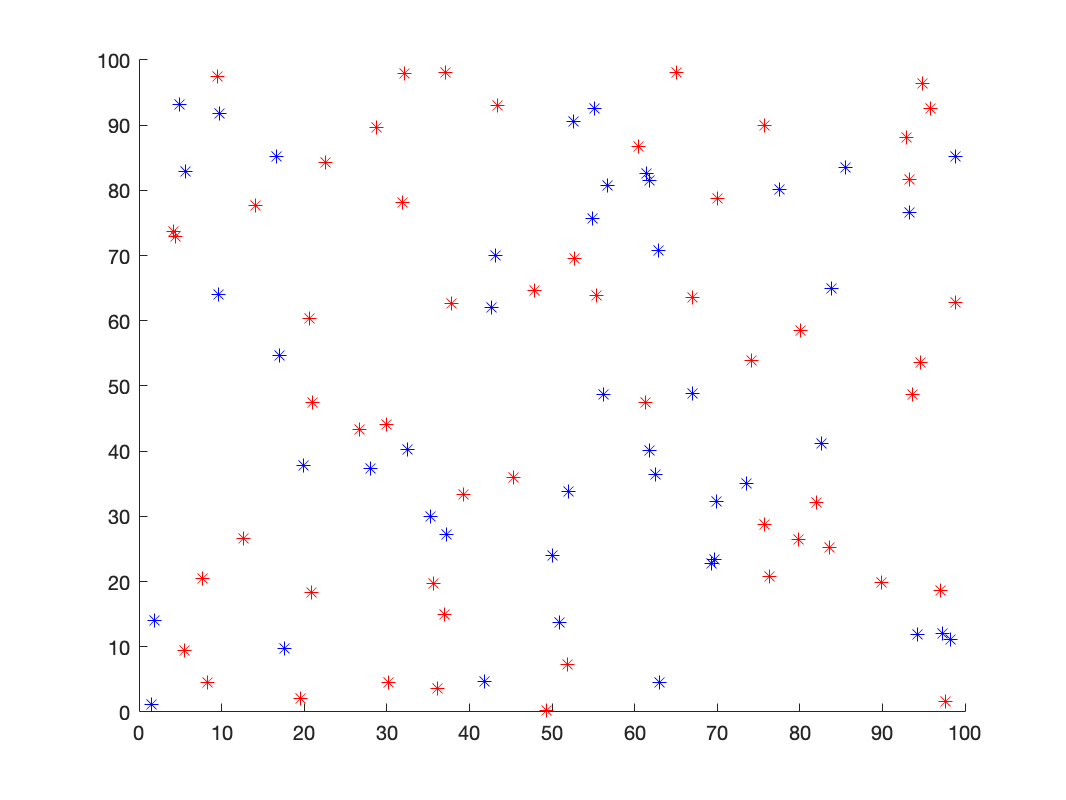

% building a microscopic model of fans
% v(ρ) = v0(1 − ρ/ρmax)2
% define space
size_x = 100;
size_y = 100;
x = 0:0.1:size_x;
y = 0:0.1:size_y;
N = 100;
v0 = 1;
v_max = 1;
rho_max = 8;

% generate N pedestrians (x,y,vx0,vy0, Vx, Vy)
pedestrians = zeros(N,6);
% set v0 for all
pedestrians(:,3) = v0;
pedestrians(:,4) = 0;
p_colours = zeros(N,3);

% init loop
for alpha = 1:N
%     place the pedestrian in a random location within boundary
    x_p = rand(1)*size_x;
    y_p = rand(1)*size_y;
    pedestrians(alpha,1)=x_p;
    pedestrians(alpha,2)=y_p;
   
%     assign to team randomly - red heading right, blue heading left
%     initially
    if randi(2)>1
%         plot(x_p,y_p, '*', Color='b');
        p_colours(alpha,:) = [0,0,1]; 
        pedestrians(alpha,3) = pedestrians(alpha,3) *-1;
    else
%         plot(x_p,y_p, '*', Color='r');
        p_colours(alpha,:) = [1,0,0];
    end
end
% timestepping
steps = 100;
figure;
for t = 1:steps
    clf
    for alpha = 1:N
        density_count = 0;
    
        % pedestrian v0 is 50% higher if majority other team within 10m
        radius = 10;
        for beta = 1:N
            if alpha ~= beta && p_colours(alpha) ~= p_colours(beta)
                if distance(pedestrians(alpha,:),pedestrians(beta,:)) < radius
                    pedestrians(alpha,3:4) = pedestrians(alpha,3:4) * 1.5;
                    density_count = density_count+1;
                end
            end
        end

        % repulsive force
        radius2 = 5;
        A = 1; 
        B = 0.1; 
        for beta = 1:N
            if alpha ~= beta && p_colours(alpha) ~= p_colours(beta)
                if distance(pedestrians(alpha,:),pedestrians(beta,:)) < radius2
                % Calculate the normalized vector between pedestrians
                normalized_vector = (pedestrians(alpha,1:2) - pedestrians(beta,1:2)) / distance(pedestrians(alpha,:),pedestrians(beta,:));

                % Calculate the angle between the velocity vector and the normalized vector
                angle = acos(dot(pedestrians(alpha,3:4), normalized_vector) / norm(pedestrians(alpha,3:4)));

                % Repulsive force components
                distance_force = A * exp(-B * distance(pedestrians(alpha,:),pedestrians(beta,:))) * normalized_vector;
                angular_force = 1 * angle * normalized_vector; 

                % Total repulsive force
                repulsive_force = distance_force + angular_force;

                % Update the velocity based on the repulsive force
                pedestrians(alpha, 3:4) = pedestrians(alpha, 3:4) + repulsive_force;
                end
            end
        end

        rho = rho_fun(density_count, radius);
        pedestrians(alpha, 5:6) = vel_fun(pedestrians(alpha,3:4), rho, rho_max);
        vel = sqrt(pedestrians(alpha,5)^2 + pedestrians(alpha,6)^2);
        if vel > v_max
            pedestrians(alpha,5:6) = pedestrians(alpha,5:6) * v_max/vel;
        end
        
        % update location (red travel right, blue travel left) with circle
        new_x = pedestrians(alpha,5) + pedestrians(alpha,1);
        new_y = pedestrians(alpha,6) + pedestrians(alpha,2);
        new_x = rem(new_x,size_x);
        new_y = rem(new_y,size_y);
        if new_x < 0
            new_x = new_x + size_x;
        end
        if new_y < 0
            new_y = new_y + size_y;
        end
        pedestrians(alpha,1:2) = [new_x,new_y];

        % reduce velocities for better visibility
        vel0 = sqrt(pedestrians(alpha,3)^2 + pedestrians(alpha,4)^2);
        if vel0 > v_max
            pedestrians(alpha,3:4) = pedestrians(alpha,3:4) * v_max/vel0;
        end

        hold on
        plot(pedestrians(alpha,1),pedestrians(alpha,2), '*', 'Color', p_colours(alpha,:));

    end
    pause(0.01)  
    hold off% Pause for 0.01 s
end

function velocity = vel_fun(v0, rho, rho_max)
       velocity = v0*(1-rho/rho_max)^2;
end

function density = rho_fun(N, radius)
        density = N/(pi*radius^2);
end

function dist = distance(alpha, beta)
    x1 = alpha(1); y1 = alpha(2);
    x2 = beta(1); y2 = beta(2);
    dist = sqrt((x2-x1)^2 + (y2-y1)^2);
end